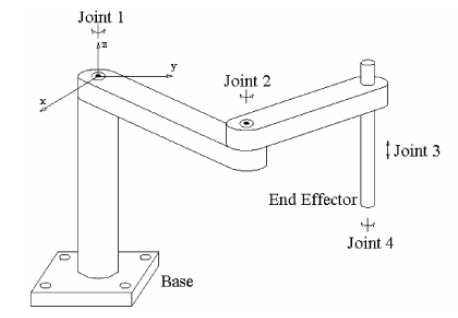

clear
clc

% Symbols for the joint angles
syms q1 q2 q3 q4 real

% Assumed Link lengths
l1 = 1;
l2 = 2;
l3 = 2;
l4 = 0.5;

% Forward Kinematics of SCARA Robot
F = Tz(l1)*Rz(q1)*Tx(l2)*Rz(q2)*Tx(-l3)*Tz(q3)*Rz(q4);
F = simplify(F)

$$F = \left(\begin{array}{cccc} \cos\left(q_{1}+q_{2}+q_{4}\right) & -\sin\left(q_{1}+q_{2}+q_{4}\right) & 0 & 2\,\cos\left(q_{1}\right)-2\,\cos\left(q_{1}+q_{2}\right)\\ \sin\left(q_{1}+q_{2}+q_{4}\right) & \cos\left(q_{1}+q_{2}+q_{4}\right) & 0 & 2\,\sin\left(q_{1}\right)-2\,\sin\left(q_{1}+q_{2}\right)\\ 0 & 0 & 1 & q_{3}+1\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## Jacobian Using Numerical Method

% Extract rotation matrix
R = simplify(F(1:3, 1:3))

$$R = \left(\begin{array}{ccc} \cos\left(q_{1}+q_{2}+q_{4}\right) & -\sin\left(q_{1}+q_{2}+q_{4}\right) & 0\\ \sin\left(q_{1}+q_{2}+q_{4}\right) & \cos\left(q_{1}+q_{2}+q_{4}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

% Differentiate F with respect to q1
F1 = Tz(l1)*Rzd(q1)*Tx(l2)*Rz(q2)*Tx(-l3)*Tz(q3)*Rz(q4)*[R^-1 zeros(3,1); 0 0 0 1];
J1 = [F1(1,4), F1(2,4), F1(3,4), F1(3,2), F1(1,3), F1(2,1)]';

% Differentiate F with respect to q2
F2 = Tz(l1)*Rz(q1)*Tx(l2)*Rzd(q2)*Tx(-l3)*Tz(q3)*Rz(q4)*[R^-1 zeros(3,1); 0 0 0 1];
J2 = [F2(1,4), F2(2,4), F2(3,4), F2(3,2), F2(1,3), F2(2,1)]';

% Differentiate F with respect to q3
F3 = Tz(l1)*Rz(q1)*Tx(l2)*Rz(q2)*Tx(-l3)*Tzd(q3)*Rz(q4)*[R^-1 zeros(3,1); 0 0 0 1];
J3 = [F3(1,4), F3(2,4), F3(3,4), F3(3,2), F3(1,3), F3(2,1)]';

% Differentiate F with respect to q4
F4 = Tz(l1)*Rz(q1)*Tx(l2)*Rz(q2)*Tx(-l3)*Tz(q3)*Rzd(q4)*[R^-1 zeros(3,1); 0 0 0 1];
J4 = [F4(1,4), F4(2,4), F4(3,4), F4(3,2), F4(1,3), F4(2,1)]';

% Full Jacobian (6x4)
J = simplify([J1 J2 J3 J4])

$$J = \left(\begin{array}{cccc} 2\,\sin\left(q_{1}+q_{2}\right)-2\,\sin\left(q_{1}\right) & 2\,\sin\left(q_{1}+q_{2}\right) & 0 & 0\\ 2\,\cos\left(q_{1}\right)-2\,\cos\left(q_{1}+q_{2}\right) & -2\,\cos\left(q_{1}+q_{2}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 1 & 1 & 0 & 1 \end{array}\right)$$